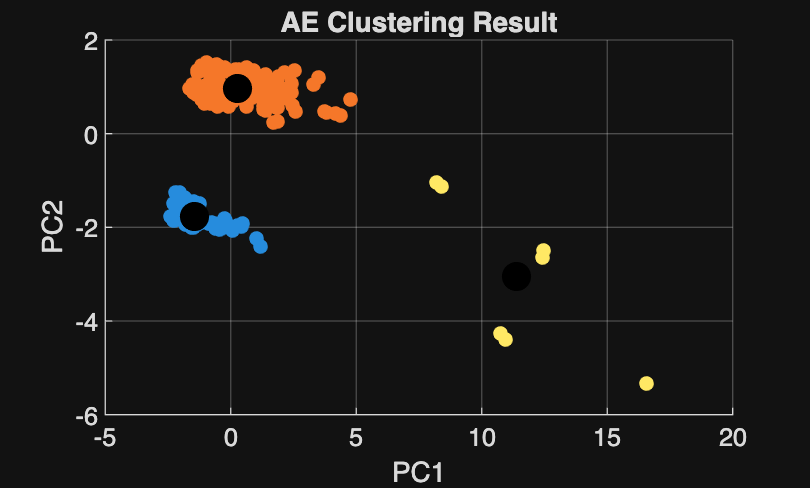

clear
clc
close all

%% PARAMETERS
fs = 4000;                % sampling rate
window_time = 0.1;        % 100 ms window
overlap = 0.5;

files = [
    "AE testing/a0016.bin"
    "AE testing/a0017.bin"
    "AE testing/a0018.bin"
];

win = round(window_time*fs);
step = round(win*(1-overlap));

features = [];

%% READ FILES AND EXTRACT FEATURES
for f = 1:length(files)
    filename = files(f);
    fid = fopen(filename,'rb');

    if fid == -1
        error("Cannot open file: %s",filename)
    end

    data = fread(fid,Inf,'uint16');
    fclose(fid);

    signal = double(data)/4096*3.3;   % convert ADC to volts
    N = length(signal);

    for i = 1:step:N-win
        segment = signal(i:i+win-1);

        %% TIME FEATURES (PURE MATH)
        mu = mean(segment);
        sigma = std(segment);
        rms_val = sqrt(mean(segment.^2));
        kurt = mean((segment-mu).^4)/(sigma^4);
        skew = mean((segment-mu).^3)/(sigma^3);
        peak = max(abs(segment));
        energy = sum(segment.^2);
        crest = peak / rms_val;

        %% FREQUENCY FEATURES
        Y = abs(fft(segment));
        Y = Y(1:floor(end/2));
        freqs = (0:length(Y)-1)*(fs/length(segment));
        spec_centroid = sum(freqs'.*Y)/sum(Y);
        band_energy = sum(Y(freqs>200 & freqs<1000));

        feat = [rms_val kurt skew peak energy crest spec_centroid band_energy];
        features = [features; feat];
    end
end

%% NORMALIZATION
X = (features - mean(features)) ./ std(features);

%% PCA USING SVD
[U,S,V] = svd(X,'econ');
score = X*V;
X_pca = score(:,1:2);

%% CUSTOM K-MEANS
K = 3;
N = size(X_pca, 1);
rng(1)

centroids = X_pca(randperm(N,K),:);

for iter = 1:100
    dist = zeros(N, K);
    for k = 1:K
        diff = X_pca - centroids(k,:);
        dist(:,k) = sum(diff.^2,2);
    end
    [~,idx] = min(dist,[],2);

    for k = 1:K
        if sum(idx==k) > 0
            centroids(k,:) = mean(X_pca(idx==k,:),1);
        end
    end
end

%% VISUALIZATION (NO TOOLBOX)
figure
hold on
colors = lines(K);
cluster_colors = ["Blue","Orange","Yellow"]; % Defined for later use

for k = 1:K
    scatter(X_pca(idx==k,1),X_pca(idx==k,2),30,colors(k,:),'filled')
end

scatter(centroids(:,1),centroids(:,2),120,'k','filled')
xlabel("PC1")
ylabel("PC2")
title("AE Clustering Result")
grid on
hold off

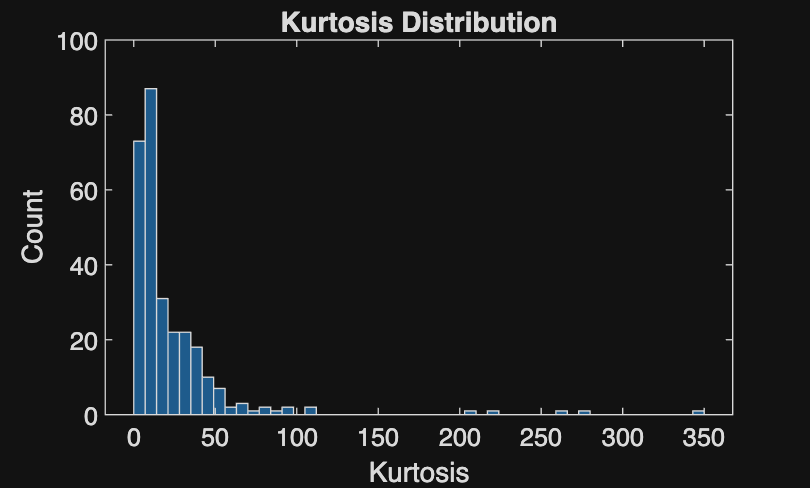


%% FEATURE DISTRIBUTION
figure
histogram(features(:,2),50)
xlabel("Kurtosis")
ylabel("Count")
title("Kurtosis Distribution")


%% PCA VARIANCE
variance = diag(S).^2 / sum(diag(S).^2);
disp("Variance explained by PC1 + PC2:")

Variance explained by PC1 + PC2:


disp(sum(variance(1:2)))

    0.9181




% Specific Values (Fixed syntax error here)
%% NUMERICAL ANALYSIS OF CLUSTERS
feature_names = ["RMS","Kurtosis","Skewness","Peak","Energy","Crest","SpecCentroid","BandEnergy"];

disp(" ")

disp("===== CLUSTER FEATURE STATISTICS =====")

===== CLUSTER FEATURE STATISTICS =====



for k = 1:K
    cluster_data = features(idx==k,:);
    fprintf("\nCluster %d\n",k)

    if isempty(cluster_data)
        disp("No data in this cluster")
        continue
    end

    mean_vals = mean(cluster_data);
    std_vals  = std(cluster_data);

    for j = 1:length(feature_names)
        fprintf("%s : mean = %.4f , std = %.4f\n", ...
            feature_names(j), mean_vals(j), std_vals(j));
    end
end


Cluster 1


RMS : mean = 0.5353 , std = 0.0019
Kurtosis : mean = 12.9255 , std = 12.7233
Skewness : mean = 1.8066 , std = 1.1371
Peak : mean = 0.5918 , std = 0.0252
Energy : mean = 114.6234 , std = 0.8049
Crest : mean = 1.1055 , std = 0.0463
SpecCentroid : mean = 102.6832 , std = 12.7144
BandEnergy : mean = 11.2254 , std = 1.8384



Cluster 2


RMS : mean = 0.5721 , std = 0.0039
Kurtosis : mean = 22.7999 , std = 20.2920
Skewness : mean = 2.8934 , std = 1.6661
Peak : mean = 0.6575 , std = 0.0419
Energy : mean = 130.9250 , std = 1.7857
Crest : mean = 1.1490 , std = 0.0684
SpecCentroid : mean = 113.7536 , std = 17.8319
BandEnergy : mean = 15.5120 , std = 3.5223



Cluster 3


RMS : mean = 0.5505 , std = 0.0144
Kurtosis : mean = 201.3521 , std = 114.6502
Skewness : mean = 12.2964 , std = 4.4892
Peak : mean = 1.0043 , std = 0.1113
Energy : mean = 121.2871 , std = 6.3420
Crest : mean = 1.8277 , std = 0.2285
SpecCentroid : mean = 327.4645 , std = 101.4847
BandEnergy : mean = 44.6921 , std = 17.4343



% Cluster size (Fixed syntax error here)
disp(" ")

disp("===== CLUSTER SIZE =====")

===== CLUSTER SIZE =====



for k = 1:K
    fprintf("Cluster %d : %d segments\n",k,sum(idx==k));
end

Cluster 1 : 91 segments
Cluster 2 : 190 segments
Cluster 3 : 7 segments



% Extra (Fixed syntax error here)
%% CLUSTER INTERPRETATION REPORT
disp(" ")

disp("========== CLUSTER INTERPRETATION REPORT ==========")

========== CLUSTER INTERPRETATION REPORT ==========



for k = 1:K
    cluster_data = features(idx==k,:);
    fprintf("\nCluster %d (%s)\n",k,cluster_colors(k))
    fprintf("Number of segments: %d\n",sum(idx==k))

    if isempty(cluster_data)
        disp("No data")
        continue
    end

    mean_vals = mean(cluster_data);
    std_vals  = std(cluster_data);
    disp("Feature statistics:")

    for j = 1:length(feature_names)
        fprintf("%s : mean = %.4f , std = %.4f\n", ...
            feature_names(j), mean_vals(j), std_vals(j));
    end
end


Cluster 1 (Blue)


Number of segments: 91


Feature statistics:


RMS : mean = 0.5353 , std = 0.0019
Kurtosis : mean = 12.9255 , std = 12.7233
Skewness : mean = 1.8066 , std = 1.1371
Peak : mean = 0.5918 , std = 0.0252
Energy : mean = 114.6234 , std = 0.8049
Crest : mean = 1.1055 , std = 0.0463
SpecCentroid : mean = 102.6832 , std = 12.7144
BandEnergy : mean = 11.2254 , std = 1.8384



Cluster 2 (Orange)


Number of segments: 190


Feature statistics:


RMS : mean = 0.5721 , std = 0.0039
Kurtosis : mean = 22.7999 , std = 20.2920
Skewness : mean = 2.8934 , std = 1.6661
Peak : mean = 0.6575 , std = 0.0419
Energy : mean = 130.9250 , std = 1.7857
Crest : mean = 1.1490 , std = 0.0684
SpecCentroid : mean = 113.7536 , std = 17.8319
BandEnergy : mean = 15.5120 , std = 3.5223



Cluster 3 (Yellow)


Number of segments: 7


Feature statistics:


RMS : mean = 0.5505 , std = 0.0144
Kurtosis : mean = 201.3521 , std = 114.6502
Skewness : mean = 12.2964 , std = 4.4892
Peak : mean = 1.0043 , std = 0.1113
Energy : mean = 121.2871 , std = 6.3420
Crest : mean = 1.8277 , std = 0.2285
SpecCentroid : mean = 327.4645 , std = 101.4847
BandEnergy : mean = 44.6921 , std = 17.4343



%% AUTOMATIC PHYSICAL INTERPRETATION
disp(" ")

disp("========== PHYSICAL INTERPRETATION ==========")

========== PHYSICAL INTERPRETATION ==========



for k = 1:K
    cluster_data = features(idx==k,:);

    if isempty(cluster_data)
        continue
    end

    mean_kurt = mean(cluster_data(:,2));
    mean_rms  = mean(cluster_data(:,1));
    mean_energy = mean(cluster_data(:,5));

    fprintf("\nCluster %d (%s)\n",k,cluster_colors(k))

    if mean_kurt < 10
        disp("Interpretation: Background noise / weak AE")
    elseif mean_kurt < 40
        disp("Interpretation: Continuous emission / vibration")
    else
        disp("Interpretation: Burst AE / impulsive event")
    end

    fprintf("Mean Kurtosis = %.2f\n",mean_kurt)
    fprintf("Mean RMS = %.4f\n",mean_rms)
    fprintf("Mean Energy = %.4f\n",mean_energy)
end


Cluster 1 (Blue)


Interpretation: Continuous emission / vibration


Mean Kurtosis = 12.93


Mean RMS = 0.5353


Mean Energy = 114.6234



Cluster 2 (Orange)


Interpretation: Continuous emission / vibration


Mean Kurtosis = 22.80


Mean RMS = 0.5721


Mean Energy = 130.9250



Cluster 3 (Yellow)


Interpretation: Burst AE / impulsive event


Mean Kurtosis = 201.35


Mean RMS = 0.5505


Mean Energy = 121.2871


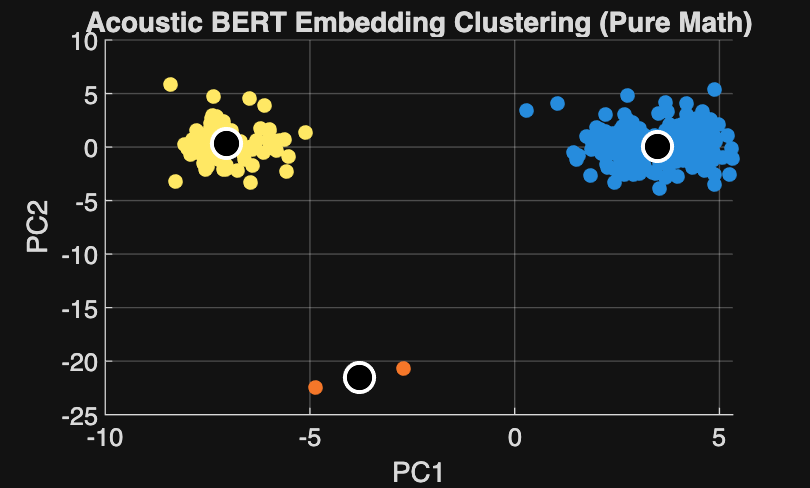

%% PARAMETERS
fs = 4000;                % sampling rate
window_time = 0.1;        % 100 ms window
overlap = 0.5;

files = [
    "AE testing/a0016.bin"
    "AE testing/a0017.bin"
    "AE testing/a0018.bin"
];

win = round(window_time*fs);             % 400 samples per window
step = round(win*(1-overlap));           % 200 samples step

% ==== BERT / TRANSFORMER PARAMETERS ====
patch_size = 20;                         % 20 samples per patch
num_patches = floor(win / patch_size);   % 20 patches per window
d_model = 64;                            % Embedding dimension
d_ff = 128;                              % Feed-forward network dimension

%% INITIALIZE UNTRAINED BERT WEIGHTS (NO TOOLBOX)
rng(42); 

% 1. Linear Projection & Positional Encoding
W_proj = randn(patch_size, d_model) * 0.01;
pos_embed = randn(num_patches, d_model) * 0.01;

% 2. Self-Attention Weights (Single Head)
W_q = randn(d_model, d_model) * 0.01;
W_k = randn(d_model, d_model) * 0.01;
W_v = randn(d_model, d_model) * 0.01;

% 3. Feed-Forward Weights
W_f1 = randn(d_model, d_ff) * 0.01;
W_f2 = randn(d_ff, d_model) * 0.01;

bert_embeddings = [];

%% READ FILES AND EXTRACT BERT EMBEDDINGS
for f = 1:length(files)
    filename = files(f);
    fid = fopen(filename,'rb');
    
    if fid == -1
        fprintf("Cannot open file: %s\n", filename);
        continue
    end

    data = fread(fid,Inf,'uint16');
    fclose(fid);

    signal = double(data)/4096*3.3;   % convert ADC to volts
    N = length(signal);

    for i = 1:step:N-win
        segment = signal(i:i+win-1);
        segment = segment(:)'; % Row vector
        
        % 1. PATCHING
        patches = reshape(segment, patch_size, num_patches)'; % Size: [num_patches, patch_size]
        
        % 2. LINEAR PROJECTION + POSITIONAL EMBEDDING
        X = patches * W_proj + pos_embed;                     % Size: [num_patches, d_model]
        
        % 3. SELF-ATTENTION
        Q = X * W_q;
        K = X * W_k;
        V = X * W_v;
        
        % Scaled Dot-Product Attention
        scores = (Q * K') / sqrt(d_model);                    % Size: [num_patches, num_patches]
        
        % Custom Softmax
        scores_exp = exp(scores - max(scores, [], 2)); 
        attn_weights = scores_exp ./ sum(scores_exp, 2);
        
        Context = attn_weights * V;                           % Size: [num_patches, d_model]
        
        % 4. ADD & NORM
        X_add = X + Context;
        mu1 = mean(X_add, 2);
        sig1 = std(X_add, 0, 2) + 1e-5;
        X_norm1 = (X_add - mu1) ./ sig1;
        
        % 5. FEED-FORWARD NETWORK
        FFN1 = max(0, X_norm1 * W_f1);                        % ReLU
        FFN2 = FFN1 * W_f2;
        
        % 6. ADD & NORM
        X_out = X_norm1 + FFN2;
        mu2 = mean(X_out, 2);
        sig2 = std(X_out, 0, 2) + 1e-5;
        X_norm2 = (X_out - mu2) ./ sig2;
        
        % 7. POOLING
        window_embedding = mean(X_norm2, 1);                  % Size: [1, d_model]
        
        bert_embeddings = [bert_embeddings; window_embedding];
    end
end

%% NORMALIZATION (Z-Score)
X_emb_norm = (bert_embeddings - mean(bert_embeddings)) ./ std(bert_embeddings);

%% PCA USING SVD
[U,S,V_pca] = svd(X_emb_norm,'econ');
score = X_emb_norm * V_pca;
X_pca = score(:,1:2);

%% CUSTOM K-MEANS
K_clusters = 3;
N_samples = size(X_pca, 1);
rng(1)

centroids = X_pca(randperm(N_samples,K_clusters),:);

for iter = 1:100
    dist = zeros(N_samples, K_clusters);
    for k = 1:K_clusters
        diff = X_pca - centroids(k,:);
        dist(:,k) = sum(diff.^2,2);
    end
    [~,idx] = min(dist,[],2);
    for k = 1:K_clusters
        if sum(idx==k) > 0
            centroids(k,:) = mean(X_pca(idx==k,:),1);
        end
    end
end

%% VISUALIZATION (NO TOOLBOX)
figure
hold on
colors = lines(K_clusters);

% Definition added here to fix the unrecognized variable error
cluster_colors = ["Blue","Orange","Yellow"]; 

for k = 1:K_clusters
    scatter(X_pca(idx==k,1),X_pca(idx==k,2),30,colors(k,:),'filled')
end

scatter(centroids(:,1),centroids(:,2),120,'k','filled','MarkerEdgeColor','w','LineWidth',1.5)

xlabel("PC1")
ylabel("PC2")
title("Acoustic BERT Embedding Clustering (Pure Math)")
grid on
hold off


%% PCA VARIANCE
variance = diag(S).^2 / sum(diag(S).^2);
disp("Variance explained by PC1 + PC2:")

Variance explained by PC1 + PC2:


disp(sum(variance(1:2)))

    0.4870




%% CLUSTER SIZE
disp(" ")

disp("===== CLUSTER SIZE =====")

===== CLUSTER SIZE =====


for k = 1:K_clusters
    fprintf("Cluster %d (%s) : %d segments\n", k, cluster_colors(k), sum(idx==k));
end

Cluster 1 (Blue) : 192 segments
Cluster 2 (Orange) : 2 segments
Cluster 3 (Yellow) : 94 segments


Use the code



%% 1. PARAMETERS & INITIALIZATION
fs = 4000;                % sampling rate
window_time = 0.1;        % 100 ms window
overlap = 0.5;

% File definitions (1 and 2 are normal, 3 is the anomaly/test)
files = [
    "/Users/komert/Documents/GitHub/REPCO_Mechatronics/AE testing/a0016.bin"
    "/Users/komert/Documents/GitHub/REPCO_Mechatronics/AE testing/a0017.bin"
    "/Users/komert/Documents/GitHub/REPCO_Mechatronics/AE testing/a0018.bin"
];

win = round(window_time * fs);           % 400 samples per window
step = round(win * (1 - overlap));       % 200 samples step

% ==== BERT PARAMETERS ====
patch_size = 20;                         % 20 samples per patch
num_patches = floor(win / patch_size);   % 20 patches per window
d_model = 64;                            % Embedding dimension
d_ff = 128;                              % Feed-forward dimension

% ==== AUTOENCODER PARAMETERS ====
input_dim = d_model;                     % Input is the BERT embedding
hidden_dim = 16;                         % Bottleneck dimension

rng(42); % Lock random seed for reproducibility

% --- Init BERT Weights ---
W_proj = randn(patch_size, d_model) * 0.01;
pos_embed = randn(num_patches, d_model) * 0.01;
W_q = randn(d_model, d_model) * 0.01;
W_k = randn(d_model, d_model) * 0.01;
W_v = randn(d_model, d_model) * 0.01;
W_f1 = randn(d_model, d_ff) * 0.01;
W_f2 = randn(d_ff, d_model) * 0.01;

% --- Init Autoencoder Weights ---
W1_ae = randn(input_dim, hidden_dim) * 0.1;
b1_ae = zeros(1, hidden_dim);
W2_ae = randn(hidden_dim, input_dim) * 0.1;
b2_ae = zeros(1, input_dim);

%% 2. BERT ENCODING (FEATURE EXTRACTION)
bert_embeddings = [];
file_labels = [];

disp('Extracting BERT Embeddings...');

Extracting BERT Embeddings...


for f = 1:length(files)
    filename = files(f);
    fid = fopen(filename, 'rb');
    
    if fid == -1
        fprintf("Cannot open file: %s\n", filename);
        continue
    end

    data = fread(fid, Inf, 'uint16');
    fclose(fid);

    signal = double(data) / 4096 * 3.3;   % Convert to volts
    N = length(signal);

    for i = 1:step:N-win
        segment = signal(i:i+win-1);
        segment = segment(:)'; % Ensure row vector
        
        % [BERT FORWARD PASS]
        patches = reshape(segment, patch_size, num_patches)';
        X = patches * W_proj + pos_embed;                     
        
        Q = X * W_q;
        K = X * W_k;
        V = X * W_v;
        
        scores = (Q * K') / sqrt(d_model);                    
        scores_exp = exp(scores - max(scores, [], 2)); 
        attn_weights = scores_exp ./ sum(scores_exp, 2);
        Context = attn_weights * V;                           
        
        X_add = X + Context;
        mu1 = mean(X_add, 2);
        sig1 = std(X_add, 0, 2) + 1e-5;
        X_norm1 = (X_add - mu1) ./ sig1;
        
        FFN1 = max(0, X_norm1 * W_f1); % ReLU                       
        FFN2 = FFN1 * W_f2;
        
        X_out = X_norm1 + FFN2;
        mu2 = mean(X_out, 2);
        sig2 = std(X_out, 0, 2) + 1e-5;
        X_norm2 = (X_out - mu2) ./ sig2;
        
        % Pool patches into a single window embedding
        window_embedding = mean(X_norm2, 1);                  
        
        bert_embeddings = [bert_embeddings; window_embedding];
        file_labels = [file_labels; f];
    end
end

%% 3. DATA PREPARATION FOR AUTOENCODER
% Train only on File 1 and 2 (Normal state)
train_idx = (file_labels == 1) | (file_labels == 2);
X_train_raw = bert_embeddings(train_idx, :);
X_all_raw = bert_embeddings;

% Normalize based on training data characteristics
mu_train = mean(X_train_raw);
sig_train = std(X_train_raw) + 1e-8;

X_train = (X_train_raw - mu_train) ./ sig_train;
X_all = (X_all_raw - mu_train) ./ sig_train;

%% 4. TRAIN AUTOENCODER ON BERT EMBEDDINGS (PURE MATH)
epochs = 1000;
learning_rate = 0.05;
N_train = size(X_train, 1);

disp('Training Autoencoder on BERT latent space...');

Training Autoencoder on BERT latent space...


for ep = 1:epochs
    % Forward Pass
    Z1 = X_train * W1_ae + b1_ae;
    A1 = max(0, Z1);           % ReLU
    Z2 = A1 * W2_ae + b2_ae;
    X_pred = Z2;               % Linear Output
    
    % MSE Loss
    error = X_pred - X_train;
    loss = mean(mean(error.^2));
    
    % Backpropagation
    dZ2 = 2 * error / N_train;
    dW2 = A1' * dZ2;
    db2 = sum(dZ2, 1);
    
    dA1 = dZ2 * W2_ae';
    dZ1 = dA1 .* (Z1 > 0);     % ReLU derivative
    dW1 = X_train' * dZ1;
    db1 = sum(dZ1, 1);
    
    % Update Weights
    W1_ae = W1_ae - learning_rate * dW1;
    b1_ae = b1_ae - learning_rate * db1;
    W2_ae = W2_ae - learning_rate * dW2;
    b2_ae = b2_ae - learning_rate * db2;
    
    if mod(ep, 200) == 0
        fprintf('Epoch %d / %d | Loss (MSE): %.4f\n', ep, epochs, loss);
    end
end

Epoch 200 / 1000 | Loss (MSE): NaN
Epoch 400 / 1000 | Loss (MSE): NaN
Epoch 600 / 1000 | Loss (MSE): NaN
Epoch 800 / 1000 | Loss (MSE): NaN
Epoch 1000 / 1000 | Loss (MSE): NaN



%% 5. ANOMALY DETECTION (RECONSTRUCTION ERROR)
disp('Calculating BERT Reconstruction Error...');

Calculating BERT Reconstruction Error...


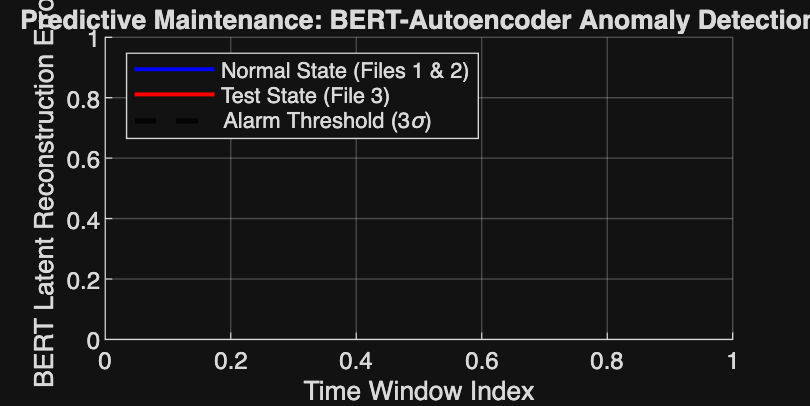


% Evaluate all data through trained Autoencoder
Z1_all = X_all * W1_ae + b1_ae;
A1_all = max(0, Z1_all);
Z2_all = A1_all * W2_ae + b2_ae;
X_all_pred = Z2_all;

% MSE per window
reconstruction_error = mean((X_all - X_all_pred).^2, 2);

%% 6. VISUALIZATION & DASHBOARD
figure('Name', 'BERT-Autoencoder Anomaly Detection', 'Position', [100, 100, 800, 400]);
hold on;

normal_data = reconstruction_error(train_idx);
plot(find(train_idx), normal_data, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Normal State (Files 1 & 2)');

anomaly_idx = (file_labels == 3);
anomaly_data = reconstruction_error(anomaly_idx);
plot(find(anomaly_idx), anomaly_data, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Test State (File 3)');

% Dynamic Threshold based on normal variance
threshold = mean(normal_data) + 3 * std(normal_data);
yline(threshold, 'k--', 'LineWidth', 2, 'DisplayName', 'Alarm Threshold (3\sigma)');

xlabel('Time Window Index');
ylabel('BERT Latent Reconstruction Error');
title('Predictive Maintenance: BERT-Autoencoder Anomaly Detection');
legend('Location', 'northwest');
grid on;
hold off;


%% 7. REPORTING
disp(' ')

disp('===== BERT-AE ANOMALY DETECTION REPORT =====')

===== BERT-AE ANOMALY DETECTION REPORT =====


fprintf('Alarm Threshold: %.4f\n', threshold);

Alarm Threshold: NaN


fprintf('Normal Windows detected as Anomaly (False Alarm): %d / %d\n', sum(normal_data > threshold), length(normal_data));

Normal Windows detected as Anomaly (False Alarm): 0 / 192


fprintf('Test Windows (File 3) crossing Threshold (True Alarm): %d / %d\n', sum(anomaly_data > threshold), length(anomaly_data));

Test Windows (File 3) crossing Threshold (True Alarm): 0 / 96
